# NSCS 344, Week 5

# Reinforcement learning with more than one stimulus

Last time we developed a reinforcement learning model that could learn about the average payoffs from a single stimulus - either a slot machine or a fractal image. Even with this simple model we could already capture some interesting neural properties where the prediction error appears to describe (at least some of) the firing of dopamine neurons.

However, we've still got a ways to go before we have something we can apply to real-world learning problems. One particularly important limitation of the model so far is that we've only thought how to apply it to learning about *one *stimulus whose relevance for the reward is assumed to be known. For example, in the fractal example, we assumed that it was the predictive power of the fractal the monkeys were learning about. In the real world, there can be any number of stimuli that might be relevant for predicting a reward and whose relevance may not be clear. Thus a key next step in the model is to capture how humans and animals learn about more than one stimulus.

As a first step in this direction, we will consider the simplest possible case of more-than-one stimulus and try to model learning about *two* stimuli. This situation is already interesting because there are many ways in which two stimuli can be combined (e.g. one before the other, both at the same time, one there part of the time, etc ...). 

## Three experiments with two stimuli

To help ground our discussion we will first consider three beahvioral experiments in which animals are trained to predict reward based on two stimuli. These experiments (or rather the effects they expose) are called: Overshadowing, Blocking, and Inhibition.

### Overshadowing

The Overshadowing experiment is perhaps the simplest two-stimuli experiments you could do.  We take two stimuli - e.g. a light and a bell presented to a pigeon in a setup like that below - and present them both at the same time.

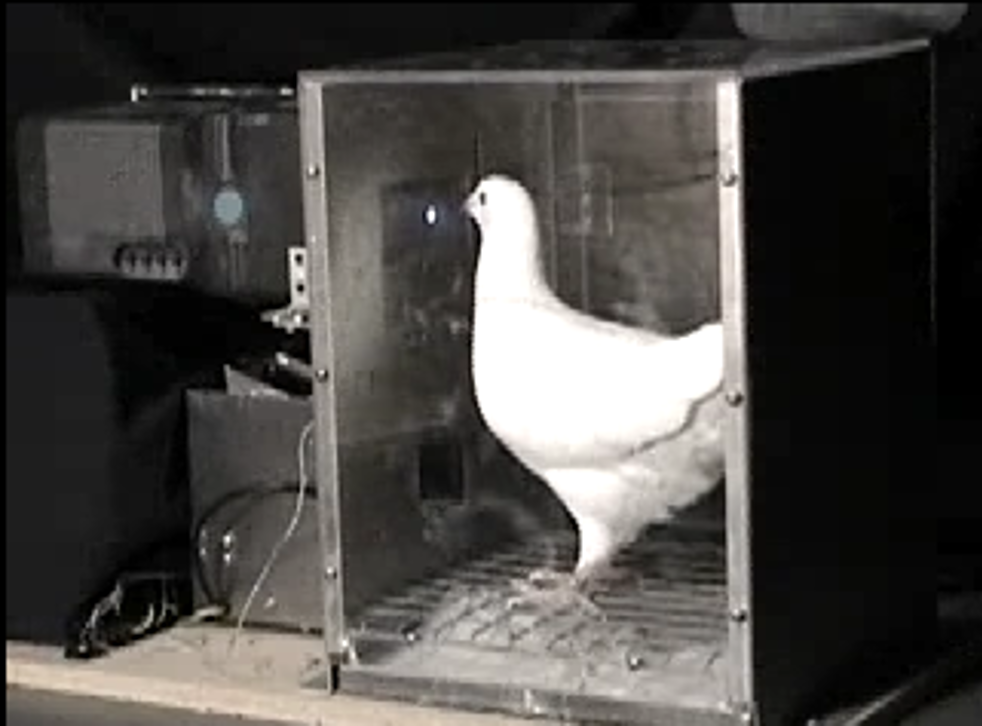

After a short delay, the reward always follows the presentation of the two stimuli.

More formally, we can describe this experiment using the simple notation


$$\mbox{training phase:} \quad A, B \rightarrow R$$


where $A$ corresponds to one stimulus (e.g. the light), $B$ the other stimulus (e.g. the bell), and $R$ the food reward.

To test learning in the Overshadowing experiment, after many training trials the stimuli are presented one at a time (e.g. $A$ alone) without reward and learning is measured as how much the pigeon pecks at the food tray - the more it pecks the more it associates the single stimulus with reward.  In our notation we represent the test phase as:


$$\mbox{test phase:} \quad A \mbox{ alone, }  B \mbox{ alone}$$


The key finding here, which we will see in the modeling section is not easily captured by our simple model, is that animals respond at an intermediate level to the stimuli alone. That is they do respond to the stimuli (as though they associate it with *some* reward), but they only respond about half as much as if they had been trained with either stimulus alone. 

All together we can summarize the Overshadowing experiment as


$$\mbox{training phase:} \quad A, B \rightarrow R$$



$$\mbox{test phase:} \quad A \mbox{ alone (weak response), }  B \mbox{ alone (weak response)}$$


### Blocking

Blocking is almost identical to Overshadowing except that *before* we present both stimuli together, we first train the animal with stimulus $A$ on its own. That is, the Blocking experiment has two training sessions and one test session.


$$\mbox{training phase 1:} \quad A \rightarrow R$$



$$\mbox{training phase 2:} \quad A, B \rightarrow R$$



$$\mbox{test phase:} \quad A \mbox{ alone, }  B \mbox{ alone}$$


Despite being identical to the Overshadowing experiment after the first phase, the behavior is quite different, with the animal responding strongly to $A$ when it is presented alone, but not responding at all $B$, as though it had never seen $B$ presented with a reward.


$$\mbox{test phase:} \quad A \mbox{ alone (strong response), }  B \mbox{ alone (no response)}$$


### Inhibition

The Blocking experiment has two kinds of trials ($A \rightarrow R$ and $A, B \rightarrow R$) which are separated out into different blocks of trials in different phases of training. In the Inhibition experiment, the two kinds of trials ($A \rightarrow R$ and $A, B \rightarrow 0$ - i.e. no reward when $A$ and $B$ are presented together) are mixed together randomly in a single training phase. So on every trial there's a 50% chance of getting an $A \rightarrow R$ trial and a 50% chance of getting an $A, B \rightarrow 0$ trial.  Schematically the experiment looks like this:


$$\mbox{training phase: } \quad A \rightarrow R \quad \mbox{ or } \quad A, B \rightarrow 0$$



$$\mbox{test phase:} \quad A \mbox{ alone, }  B \mbox{ alone}$$


Despite only seeing $A$ paired with reward half the time, behaviorally animals respond strongly to $A$ alone.  In contrast, despite never seeing $B$ paired with a *punishment*, they find $B$ aversive and avoid it when it is presented alone, as though they have learned to associate this neutral cue with negative value.


$$\mbox{test phase:} \quad A \mbox{ alone (strong response), }  B \mbox{ alone (negative response)}$$


## Simulating the two-stimulus tasks

Before we build models of learning we need to build models of the tasks. To do this, we will develop three functions - one for each task - that output which stimuli are present and what the reward is on every trial of that experiment.  If we do that, then running the models will be easy because we can use the same model functions for all of the tasks. For simplicity we will omit the testing phase, instead we will just take the values we associate with each stimulus as a proxy for the response.

Overshadowing is pretty easy, $A$ and $B$ are always present and the reward is always 1.  We can implement this in a function as

This just sets $r$, $A$ and $B$ to 1 for every trial. $T$ is the number of trials in our experiment. So now, in my script I can simulate the experiment like this

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = overshadowing(T);

Blocking is slightly more complicated because we have two phases of learning. Let's assume that half the trials are in one phase and half in the other

*Note: I used the "round" function when computing the number of trials in the first phase (T1). Round, rounds a number ot the nearest whole number. This helps us avoid errors in the case where the total number of trials is odd.*

*Note also: the second loop goes over the last set of trials from T1+1 - the first trial of phase 2 - to T - the end of phase 2.*

In my script I can then simulate blocking like this

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = blocking(T);

Finally, for inhibition we only have one phase, but we need to determine the trial type randomly.  We can do this using the binornd function ...

I can then simulate the inhibition experiment like this ...

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = inhibition(T);

## A naive model

Perhaps the simplest way to model learning about multiple stimuli is to treat the stimuli completely independently and learn a value for each of them.  For example, when stimulus $A$ is present on a trial, we will update the value of $A$ like this


$$V^A_t = V^A_{t-1} + \alpha \left(r_t - V^A_{t-1}\right)$$


Likewise when stimulus $B$ is present on a trial we will update the value of $B$ like this


$$V^B_t = V^B_{t-1} + \alpha \left(r_t - V^B_{t-1}\right)$$


Before we can translate this into code, we also need to consider how we update $V^A$ and $V^B$ when the respective stimuli are *not* present - e.g. what do we do with the value of $B$ on the $A\rightarrow R$ trial? Perhaps the easiest thing we can do is to say that the values don't update when the stimuli aren't present.  So when $A$ is absent, we write


$$V^A_t = V^A_{t-1}$$


and likewise when $B$ is absent we write


$$V^B_t = V^B_{t-1}$$


To implement this learning model in code we will then do something like this (first in a script then we will translate it to a function)

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = overshadowing(T);

% learning rate
alpha = 0.1;

for i = 1:T
    
    if A(i) == 1
        % update by prediction error if A is present
        VA(i) = VA(i-1) + alpha * (r(i) - VA(i-1));
    else
        % do not change value of A if A is absent
        VA(i) = VA(i-1)
    end
    
    if B(i) == 1
        % update by prediction error if B is present
        VB(i) = VB(i-1) + alpha * (r(i) - VB(i-1));
    else
        % do not change value of B if B is absent
        VB(i) = VB(i-1)
    end
    
end

However, there's a problem with this code.  Can you see what it is?  It's a problem we encountered last week too ... if you can't see it, try running the code and see if you can make sense of the error message ...

Did you see it? The problem occurs on the very first trial in the loop when $i = 1$, specifically when we refer to VA(i-1), which equals VA(0), and VB(i-1), which equals VB(0).  Remember that Matlab *hates *the number 0 as an index.  So just like we did last week, we need to do something special for the very first trial.

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = overshadowing(T);

% learning rate
alpha = 0.1;

for i = 1:T
    
    % exception for first trial
    if i == 1
        
        if A(i) == 1
            % if A is present initialize it to alpha * r(1)
            VA(i) = alpha * r(i);
        else
            % if A is absent initialize it to 0
            VA(i) = 0;
        end
        if B(i) == 1
            % if B is present initialize it to alpha * r(1)
            VB(i) = alpha * r(i);
        else
            % if B is absent initialize it to 0
            VB(i) = 0;
        end
        
    else % update for remaining trials
        
        if A(i) == 1
            % update by prediction error if A is present
            VA(i) = VA(i-1) + alpha * (r(i) - VA(i-1));
        else
            % do not change value of A if A is absent
            VA(i) = VA(i-1);
        end
        
        if B(i) == 1
            % update by prediction error if B is present
            VB(i) = VB(i-1) + alpha * (r(i) - VB(i-1));
        else
            % do not change value of B if B is absent
            VB(i) = VB(i-1);
        end
        
    end
end

Obviously this code is a little long, but we can shorten it quite a bit if we use the indicator variables A(i) and B(i).  In particular, instead of writing things like ...

we can replace all of this with

Because when A(i) is zero the whole second term disappears!  Working through all the code we can then simplify things to

for i = 1:T
    
    % exception for first trial
    if i == 1
        
        % if A is present initialize it to alpha * r(1)
        % if A is absent initialize it to 0
        VA(i) = alpha * r(i) * A(i);
    
        % if B is present initialize it to alpha * r(1)
        % if B is absent initialize it to 0
        VB(i) = alpha * r(i) * B(i);
        
    else % update for remaining trials
        
        % update by prediction error if A is present
        % do not change value of A if A is absent
        VA(i) = VA(i-1) + alpha * (r(i) - VA(i-1)) * A(i);
        
        % update by prediction error if B is present
        % do not change value of B if B is absent
        VB(i) = VB(i-1) + alpha * (r(i) - VB(i-1));
        
    end
end

We can then hide all this code away inside a function ...

*Note: I did something slightly different this week when i = 1.  In particular if a stimulus was present I set its value to *$\alpha \times r(1)$ *not just *$r(1)$* like we did last week. Including the *$\alpha$ *is what we get if we assume the initial value (e.g. *$V^A(0)$)* is 0 and makes for slightly nicer plots down below ...*

## Putting the naive model all together

Finally, let's implement the naive model for overshadowing ...

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = overshadowing(T);

% learning rate
alpha = 0.1;

[VA, VB] = naiveModel(alpha, r, A, B);

Then let's plot the results

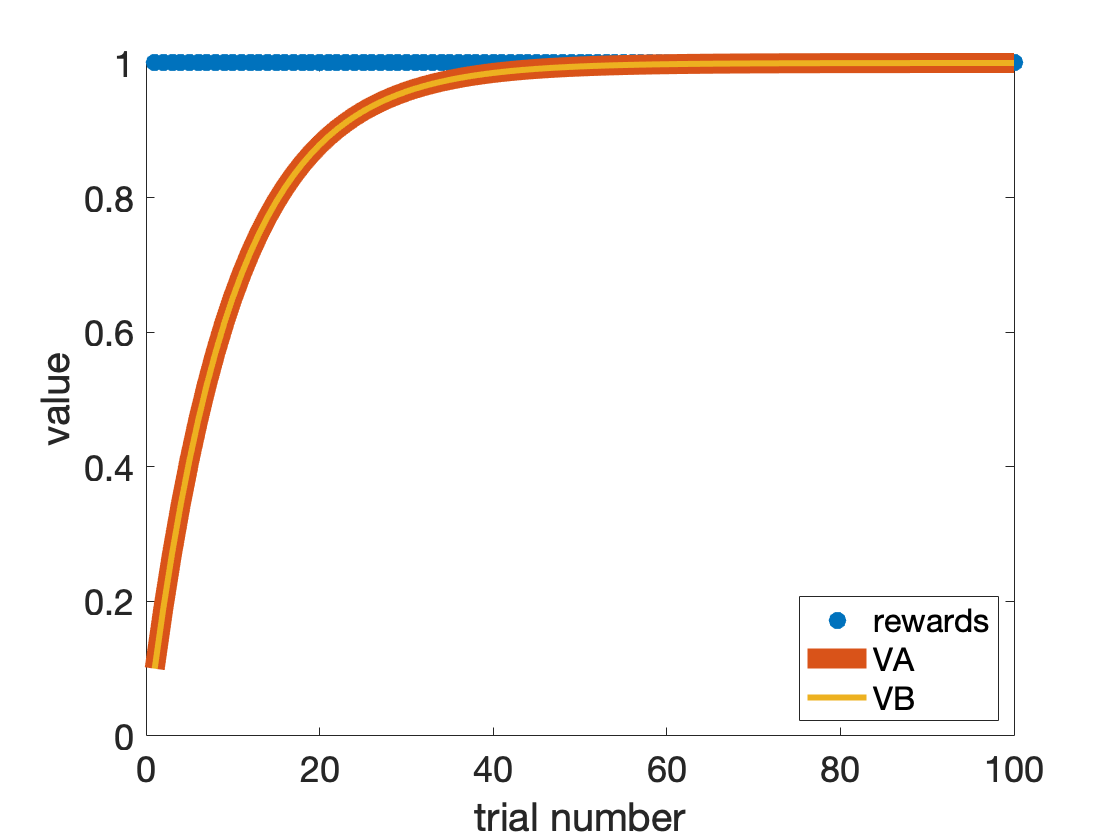

clf;
plot(r,'.', 'markersize', 30)
hold on;
l = plot(VA);
l(2) = plot(VB);
xlabel('trial number')
ylabel('value')
set(l, 'linewidth', 3)
set(l(1), 'linewidth', 10)
set(gca, 'fontsize', 18)
legend({'rewards' 'VA' 'VB'}, 'location', 'southeast')

So our model of naive overshadowing suggests that $V^A$ and $V^B$ sould be identical and high - not what is seen experimentally, which suggests that the naive model is wrong.

In the Assignment you will see how the naive model performs even worse on blocking and inhibition.

## The Rescorla-Wagner model

Naively associating stimuli with rewards cannot explain behavior on overshadowing, blocking or inhibition experiments. So is there any theory that can explain these findings? In one of great papers of 20th Century Psychology, Rescorla and Wagner (summarized [here](http://www.scholarpedia.org/article/Rescorla-Wagner_model#:~:text=The%20Rescorla%2DWagner%20model%20is,result%20of%20a%20conditioning%20trial.)) proposed a solution to these problems with one, very simple intution: that learning should only occur when there is a prediction error. This remarkably simple idea can explain away all of the problems with overshadowing, blocking and inhibition.

But first, let's make the model more explicit. In the Rescorla-Wagner model, we still learn a separate value for each stimulus, $V^A$ and $V^B$, but, instead of having a separate prediction error for each of them, we only have a single reward prediction error that correponds to the different between the actual reward and the *sum* of the predictions from each stimulus ...


$$\mbox{predicition error, } \delta = r_t - \sum_S V^S_{t-1}
$$


where the sum over $S$ corresponds to the sum over all stimuli that are present on this trial.  For example, when both $A$ and $B$ are present, the prediction error is


$$\delta = r_t - V^A_{t-1} - V^B_{t-1}$$


But when only $A$ is present, the prediction error is


$$\delta = r_t - V^A_{t-1}$$


This single prediction error is then used to update the values for $A$ and $B$ 


$$V^A_t = V^A_{t-1} + \alpha \delta$$



$$V^B_t = V^B_{t-1} + \alpha \delta$$


Although of course, when a stimulus is *not* present on a trial we keep it's value the same.

Let's implement this model and see how it can account for overshadowing.  In the Assignment you will also see how it can account for blocking and inhibition ...

## Implementing the Rescorla-Wagner model

Following the process we used to build the naive model, let's first implement the Rescorla Wagner model in a script.  First, copy-pasting from what we had before for the setup ...

clear

% number of trials
T = 100;

% simulate the experiment
[r, A, B] = overshadowing(T);

% learning rate
alpha = 0.1;

Then, we need to implement the equations, first for prediction error we will need a line like this ...

*Note: By multiplying the value of each option by its indicator variable (A(i) or B(i)), this means that the value of each option is only used to compute the prediction error if the stimulus is present.*

Next for the value updates ...

Where again, including the indicator variables only applies the update when a stimulus is present.

Finally we need to put it all into a loop and remember to treat the first trial differently ...

for i = 1:T
    if i == 1
        
        % special case for first trial, assume initial values are zero
        % compute prediction error
        delta = r(i) - A(i) * 0 - B(i) * 0;
        
        % update values
        VA(i) = 0 + alpha * delta * A(i);
        VB(i) = 0 + alpha * delta * B(i);
        
    else
        % compute prediction error
        delta = r(i) - A(i) * VA(i-1) - B(i) * VB(i-1);
        
        % update values
        VA(i) = VA(i-1) + alpha * delta * A(i);
        VB(i) = VB(i-1) + alpha * delta * B(i);
        
    end
end

Then put the whole thing into a function like this ...

and finally plot the results ...

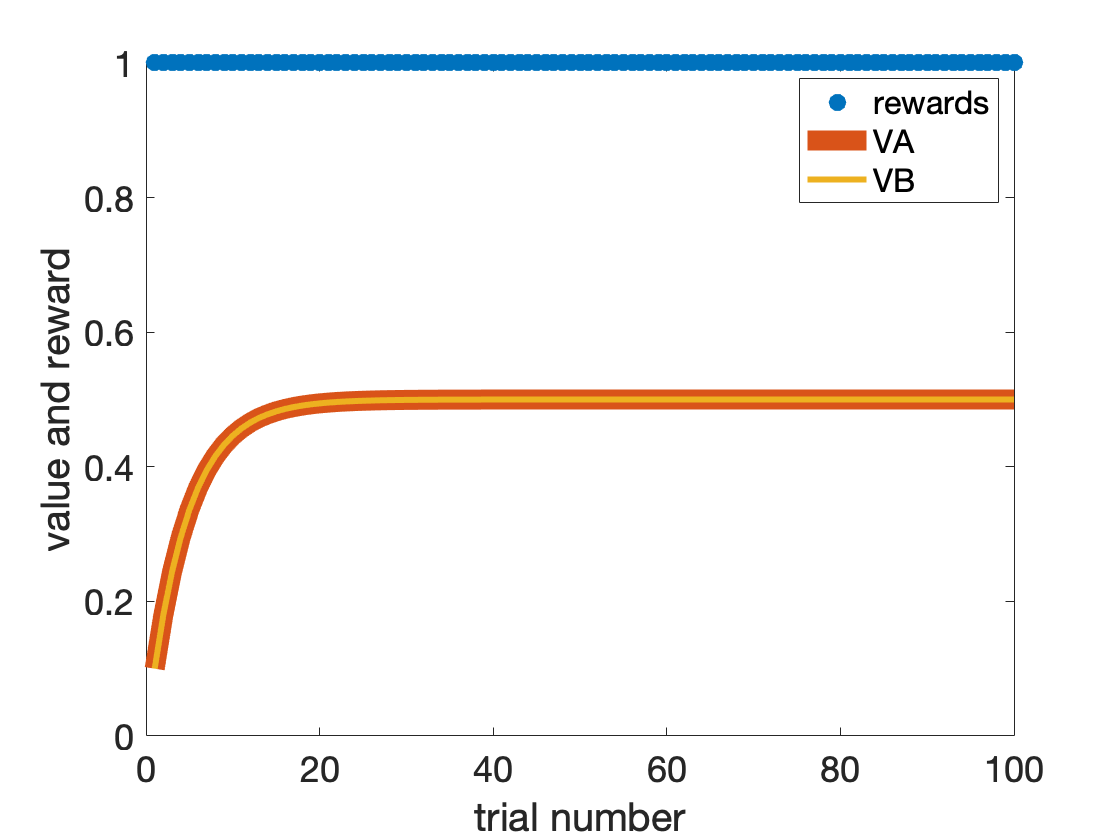

clf;
plot(r, '.', 'markersize', 30)
hold on;
l = plot(VA);
l(2) = plot(VB);
set(l(1), 'linewidth', 10)
set(l(2), 'linewidth', 3)
xlabel('trial number')
ylabel('value and reward')
legend({'rewards' 'VA' 'VB'})
set(gca, 'fontsize', 18)

Note that for Overshadowing $V^A$ and $V^B$  still have the same value, but they top out at a value of 0.5 so that when they are presented together they predict 1 unit of reward, which leads to a prediction error of zero at the end of learning.

These final values of 0.5 are consistent with the "weak responding" we see in the experiments with this task. When you implement the same model for blocking and inhibition, you will see that $V^A$ and $V^B$ end up being quite different in these cases.